True DoAs (deg):
  -44.0721  -33.4602    9.0948

Estimated DoAs (deg):
    9.1000  -44.1000  -33.4000

Doppler shifts (Hz):
   1.0e+03 *

   -1.7092    2.3295    1.3069



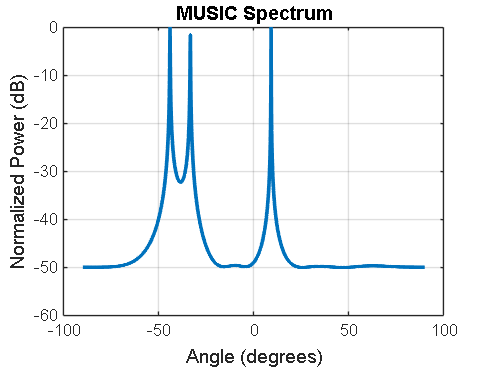

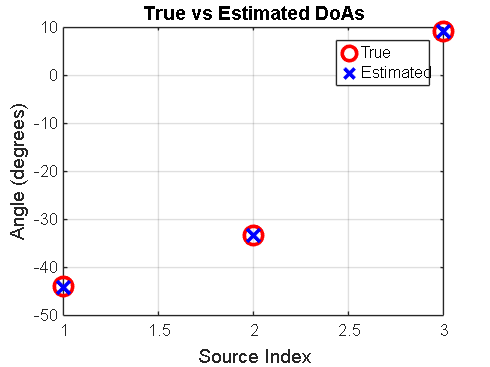

% AOA_MUSIC_V2X.m – Step 1: V2X AoA Estimation using MUSIC Algorithm

% Simulation parameters
M = 8;                      % Number of antennas
K = 3;                      % Number of sources (e.g., vehicles)
d = 0.0107 / 2;             % Distance between antennas (half-wavelength)
wavelength = 0.0107;        % Wavelength at 28 GHz (in meters)
SNR = 20;                   % Signal-to-noise ratio (dB)
fs = 1e6;                   % Sampling frequency in Hz
N = 1024;                   % Number of snapshots

% Generate V2X synthetic signal
[x, ~, true_DoAs, doppler_shifts] = v2x_signal_simulation(M, K, d, wavelength, SNR, N, fs);

% Apply MUSIC algorithm
doa_estimates = algo(x, M, K, d, wavelength);

% Plot results
plot_results(x, doa_estimates, M, K, d, wavelength, true_DoAs, doppler_shifts);

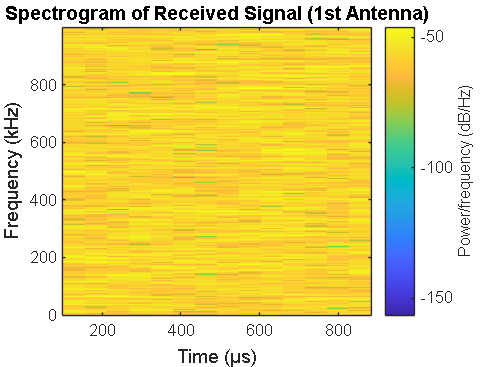


% Plot spectrogram
figure;
spectrogram(x(1, :), 256, 200, 512, fs, 'yaxis');
title('Spectrogram of Received Signal (1st Antenna)');


% -------------------------------------
% Signal Generation Function
function [x, A, true_DoAs, doppler_shifts] = v2x_signal_simulation(M, K, d, wavelength, SNR, N, fs)
    c = 3e8;                % Speed of light
    fc = 28e9;              % Carrier frequency
    t = (0:N-1)/fs;         % Time vector

    % Generate random angles and vehicle speeds
    true_DoAs = sort(-60 + 120 * rand(1, K));      % Random DoAs between -60 and +60
    speeds = -30 + 60 * rand(1, K);                % Speeds between -30 and 30 m/s
    doppler_shifts = fc * speeds / c;              % Doppler shifts in Hz

    theta = deg2rad(true_DoAs);
    A = exp(-1i * 2 * pi * d * (0:M-1).' * sin(theta) / wavelength); % Steering matrix

    % Signal with Doppler shift
    S = zeros(K, N);
    for k = 1:K
        S(k,:) = sqrt(0.5)*(randn(1, N) + 1i*randn(1, N)) .* exp(1i*2*pi*doppler_shifts(k)*t);
    end

    noise_var = 10^(-SNR/10) * trace(A*(S*S')*A') / (M*N);
    noise = sqrt(noise_var/2)*(randn(M, N) + 1i*randn(M, N));
    x = A*S + noise;
end

% -------------------------------------
% MUSIC AoA Estimation Algorithm
function doa_estimates = algo(x, M, K, d, wavelength)
    theta = -90:0.1:90;  % Scan angles
    [Vn, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta);

    [~, idx] = sort(Pmusic, 'descend');
    idx = idx(1:K);
    initial_DoAs = theta(idx);

    doa_estimates = zeros(1, K);
    for i = 1:K
        err = @(xval) abs(1 / abs((a(xval, d, M, wavelength)' * Vn) * (Vn' * a(xval, d, M, wavelength))) - Pmusic(idx(i)));
        doa_estimates(i) = fminsearch(err, initial_DoAs(i));
    end
end

% -------------------------------------
% Steering Vector Function
function a_vec = a(angle, d, M, wavelength)
    a_vec = exp(-1i * 2 * pi * d * (0:M-1).' * sind(angle) / wavelength);
end

% -------------------------------------
% MUSIC Spectrum Calculation
function [Vn, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta)
    Rxx = (x * x') / size(x, 2);
    [V, D] = eig(Rxx);
    [~, idx] = sort(diag(D), 'descend');
    V = V(:, idx);
    Vn = V(:, K+1:end);

    Pmusic = arrayfun(@(ang) 1 / abs((a(ang, d, M, wavelength)' * Vn) * ...
                                     (Vn' * a(ang, d, M, wavelength))), theta);
end

% -------------------------------------
% Results Plotting Function
function plot_results(x, doa_estimates, M, K, d, wavelength, true_DoAs, doppler_shifts)
    theta = -90:0.1:90;
    [~, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta);

    disp('True DoAs (deg):'); disp(true_DoAs);
    disp('Estimated DoAs (deg):'); disp(doa_estimates);
    disp('Doppler shifts (Hz):'); disp(doppler_shifts);

    % MUSIC Spectrum
    figure;
    plot(theta, 10 * log10(abs(Pmusic)/max(abs(Pmusic))), 'LineWidth', 2);
    xlabel('Angle (degrees)');
    ylabel('Normalized Power (dB)');
    title('MUSIC Spectrum');
    grid on;

    % True vs Estimated
    figure;
    plot(1:K, sort(true_DoAs), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
    hold on;
    plot(1:K, sort(doa_estimates), 'bx', 'LineWidth', 2, 'MarkerSize', 10);
    xlabel('Source Index');
    ylabel('Angle (degrees)');
    title('True vs Estimated DoAs');
    legend('True', 'Estimated');
    grid on;
end
